# *Drosophila* Body dynamics

clear; close all; clc

Body Inertia

% I = 5.2e-13; % Body Interia [N*m*s^2]
I_b = 5.9e-13; % Body Interia [N*m*s^2] +- 3.3e-14

Body Damping

% C = 5.2e-13; % Body Damping [N*m*s]
C_b = 1.1e-12; % Body Damping [N*m*s] +- 2.3e-11

Time Constant

tau = I_b/C_b; % time constant

Body Plant

G = tf(1,[tau 1])


G =
 
       1
  ------------
  0.5364 s + 1
 
Continuous-time transfer function.



Delay Simulations

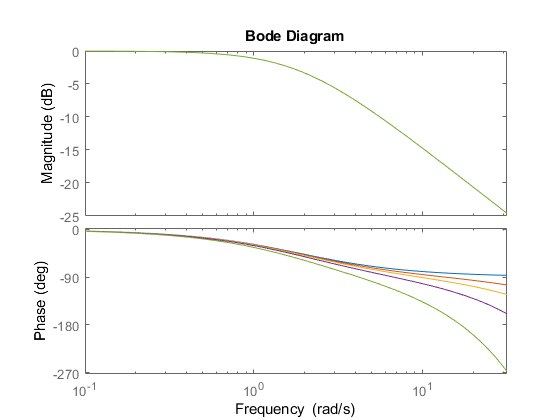

delay = [0 10 20 40 100]*10^(-3);

FIG = figure (1) ; clf
% FIG.Position = [2 2 5 5];
hold on
for kk = 1:length(delay)
    G.OutputDelay = delay(kk);
    bode(G)
end
xlim(10.^[-1 1.5])

% yticks([-2000:100:2000])
% ylim([-360 0])

# *Drosophila* Body dynamics with head

clear; close all; clc

Body Inertia

% I = 5.2e-13; % Body Interia [N*m*s^2]
I_b = 5.9e-13; % Body Interia [N*m*s^2] +- 3.3e-14

Body Damping

% C = 5.2e-13; % Body Damping [N*m*s]
C_b = 1.1e-12; % Body Damping [N*m*s] +- 2.3e-11

Time Constant

tau = I_b/C_b; % time constant

Body Plant

G = tf(1,[tau 1]);
G.OutputDelay = 40e-3;

Head Inertia

I_h = 0.2*I_b;

Head Natural Frequency (rad/s)

wn = 50;

Head stiffness (N*m/rad)

K_h = wn^(2)*I_b;

Head critical damping (N*m*s/rad)

cc = 2*sqrt(K_h*I_b);
z = 1.2;

Head damping (N*m*s/rad)

C_h = z*cc;

Head Plant

P = tf(1,[I_h C_h K_h]);

Head Controller

Ctrl = 1;

Reference to Error

R2E = (1/(1+P*Ctrl));
R2E.OutputDelay = 10e-3


R2E =
 
                 1.18e-13 s^2 + 7.08e-11 s + 1.475e-09
  exp(-0.01*s) * -------------------------------------
                     1.18e-13 s^2 + 7.08e-11 s + 1
 
Continuous-time transfer function.



Reference to Body

R2B = R2E*G


R2B =
 
                                                         
                    1.18e-13 s^2 + 7.08e-11 s + 1.475e-09
                                                         
  exp(-0.05*s) * -------------------------------------------
                                                            
                 6.329e-14 s^3 + 3.809e-11 s^2 + 0.5364 s   
                                                            
                                                         + 1
                                                            
 
Continuous-time transfer function.



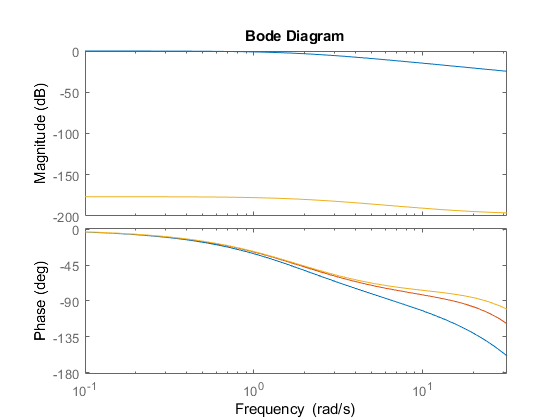

FIG = figure (1); clf
hold on
bode(G)
bode(R2B)
G.OutputDelay = 0e-3;
R2E.OutputDelay = 40e-3;
R2B = R2E*G;
bode(R2B)
xlim(10.^[-1 1.5])

% yticks([-2000:100:2000])
% ylim([-360 0])